%Experiment 1: Diode-Connected Transitor Characteristics
clear
clf
load('Experiment 1/IinVout/Vout.mat')
load('Experiment 1/IinVout/Iin.mat')
semilogy(Vout, Iin, '.')
hold on
title("Experiment 1: Diode-Connected Transitor Characteristics")
xlabel("Voltage (V)")
ylabel("Current (A")
grid on
%plot(Iin,Vout,".")

%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vout, log(Iin), 5e-4);
Is = exp(bmax);
Ut = 1/mmax

Ut = 0.0258


th_Vout = Ut*log((Iin)/Is);
%plot(Iin, th_Vout)
semilogy(th_Vout, Iin)


%Vin Iout
load('Experiment 1/VinIout/Vin.mat')
load('Experiment 1/VinIout/Iout.mat')
%plot(Vin, Iout,".")
semilogy(Vin, Iout, '.')

%line of best fit
[first2, last2, mmax2, bmax2, Nmax2]=linefit(Vin, log(Iout), 5e-4);
Is2 = exp(bmax2)

Is2 = 4.7192e-15

Ut2 = 1/mmax2

Ut2 = 0.0261

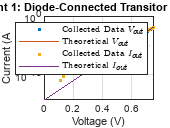


th_Iout = Is2*exp(Vin/Ut2);
th_Vout = Ut2*log((Iin)/Is2);
%plot(Iin, th_Vout)
semilogy(Vin, th_Iout)

legend("Collected Data $V_{out}$", "Theoretical $V_{out}$", "Collected Data $I_{out}$", "Theoretical $I_{out}$", "Interpreter", "latex")

hold off

%Experiment 1: 
clf
R = diff(Vout)./diff(Iin)

R = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0011    0.0017    0.0021    0.0032    0.0040    0.0062    0.0077    0.0113    0.0157    0.0205    0.0321    0.0397    0.0620    0.0766    0.1197    0.1478    0.2311    0.2854    0.4461    0.5510    0.8613    1.0638    1.6630    2.2593


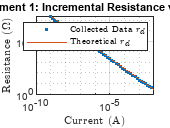

loglog(Iin(2:end), R, '.')
hold on
title("Experiment 1: Incremental Resistance vs Current")
xlabel("Current (A)", "Interpreter", "latex")
ylabel("Resistance ($\Omega$)", "Interpreter", "latex")
grid on

% line of best fit
th_R = Ut./Iin; % = dv/dI
loglog(Iin, th_R)

legend("Collected Data $r_{d}$", "Theoretical $r_{d}$", "Interpreter", "latex")

clear
clf

Ut = 0.0261;
Is = 4.7192*(10^-15)

Is = 4.7192e-15

Ion_100k = Ut/100000

Ion_100k = 2.6100e-07

Ion_10k = Ut/10000

Ion_10k = 2.6100e-06

Ion_1k = Ut/1000

Ion_1k = 2.6100e-05

Von_100k = Ut*log(Ion_100k/Is) %10

Von_100k = 0.4653

Von_10k = Ut*log(Ion_10k/Is) % 11

Von_10k = 0.5254

Von_1k = Ut*log(Ion_1k/Is) %12

Von_1k = 0.5855


load('Experiment 2/100kohmnew/Vout.mat')
load('Experiment 2/100kohmnew/Vin.mat')
load('Experiment 2/100kohmnew/Iout.mat')
Vin_100k = Vin;
Vout_100k = Vout;
Iout_100k = Iout;
[first_V100k, last_V100k, mmax_V100k, bmax_V100k, Nmax_V100k]=linefit(Vin_100k(1:10), Vout_100k(1:10), 5e-4)

first_V100k = 1

last_V100k = 10

mmax_V100k = 0.9869

bmax_V100k = 0.0093

Nmax_V100k = 10

[first_I100k, last_I100k, mmax_I100k, bmax_I100k, Nmax_I100k]=linefit(Vin_100k(1:10), log(Iout_100k(1:10)), 5e-4)

first_I100k = 0

last_I100k = 0

mmax_I100k = 0

bmax_I100k = 0

Nmax_I100k = 0

Is_I100k = exp(bmax_I100k)

Is_I100k = 1

Ut_I100k = 1/mmax_I100k

Ut_I100k = Inf

Iout_100k_theoretical = Is_I100k*exp(Vin_100k/Ut_I100k);
[first_L100k, last_L100k, mmax_L100k, bmax_L100k, Nmax_L100k]=linefit(Vin_100k(10:end), Iout_100k(10:end), 5e-4)

first_L100k = 5

last_L100k = 52

mmax_L100k = 9.7525e-06

bmax_L100k = -5.0844e-06

Nmax_L100k = 48


load('Experiment 2/10kohmnew/Vout.mat')
load('Experiment 2/10kohmnew/Vin.mat')
load('Experiment 2/10kohmnew/Iout.mat')
Vin_10k = Vin;
Vout_10k = Vout;
Iout_10k = Iout;
[first_V10k, last_V10k, mmax_V10k, bmax_V10k, Nmax_V10k]=linefit(Vin_10k(1:10), Vout_10k(1:10), 5e-4)

first_V10k = 1

last_V10k = 10

mmax_V10k = 0.9984

bmax_V10k = 0.0079

Nmax_V10k = 10

[first_I10k, last_I10k, mmax_I10k, bmax_I10k, Nmax_I10k]=linefit(Vin_10k(3:15), log(Iout_10k(3:15)), 5e-4)

first_I10k = 0

last_I10k = 0

mmax_I10k = 0

bmax_I10k = 0

Nmax_I10k = 0

Is_I10k = exp(bmax_I10k)

Is_I10k = 1

Ut_I10k = 1/mmax_I10k

Ut_I10k = Inf

Iout_10k_theoretical = Is_I10k*exp(Vin_10k/Ut_I10k);
[first_L10k, last_L10k, mmax_L10k, bmax_L10k, Nmax_L10k]=linefit(Vin_10k, Iout_10k, 5e-4);
load('Experiment 2/1kohmnew/Vout.mat')
load('Experiment 2/1kohmnew/Vin.mat')
load('Experiment 2/1kohmnew/Iout.mat')
Vin_1k = Vin;
Vout_1k = Vout;
Iout_1k = Iout;
[first_V1k, last_V1k, mmax_V1k, bmax_V1k, Nmax_V1k]=linefit(Vin_1k(1:10), Vout_1k(1:10), 5e-4)

first_V1k = 1

last_V1k = 10

mmax_V1k = 0.9998

bmax_V1k = 0.0076

Nmax_V1k = 10

[first_I1k, last_I1k, mmax_I1k, bmax_I1k, Nmax_I1k]=linefit(Vin_1k(3:15), log(Iout_1k(3:15)), 5e-4)

first_I1k = 0

last_I1k = 0

mmax_I1k = 0

bmax_I1k = 0

Nmax_I1k = 0

Is_I100k = exp(bmax_I100k)

Is_I100k = 1

Ut_I100k = 1/mmax_I100k

Ut_I100k = Inf

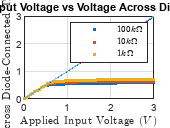

Iout_100k_theoretical = Is_I100k*exp(Vin_100k/Ut_I100k);
[first_L100k, last_L100k, mmax_L100k, bmax_L100k, Nmax_L100k]=linefit(Vin_100k, Iout_100k, 5e-4);

plot(Vin_100k, Vout_100k, '.');
hold on;
grid on;
plot(Vin_10k, Vout_10k, '.');
plot(Vin_1k, Vout_1k, '.');
plot(Vin_100k, (Vin_100k*mmax_V100k) + bmax_V100k);
plot(Vin_10k, (Vin_10k*mmax_V10k) + bmax_V10k);
plot(Vin_1k, (Vin_1k*mmax_V1k) + bmax_V1k);
legend("$100k\Omega$", "$10k\Omega$", "$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Voltage Across Diode-Connected Transistor")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Voltage Across Diode-Connected Transistor ($V$)", "Interpreter", "latex")
hold off;

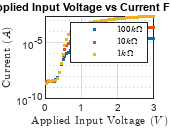


semilogy(Vin_100k, Iout_100k, '.');
hold on;
grid on;
semilogy(Vin_10k, Iout_10k, '.');
semilogy(Vin_1k, Iout_1k, '.');
legend("$100k\Omega$", "$10k\Omega$", "$1k\Omega$", "Interpreter","latex")
title("Experiment 2: Applied Input Voltage vs Current Flowing into the Circuit")
xlabel("Applied Input Voltage ($V$)", "Interpreter", "latex")
ylabel("Current ($A$)", "Interpreter", "latex")
hold off;

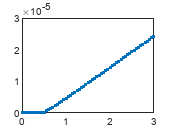


plot(Vin_100k, Iout_100k, '.');

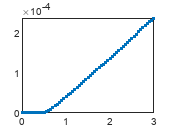

plot(Vin_10k, Iout_10k, '.');

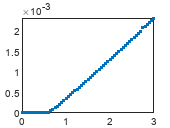

plot(Vin_1k, Iout_1k, '.');